# Lifting scheme development

A lifting scheme is given by three steps. The split step breaks the signal into even and odd elements. The predict step updates the odd value for the next resolution level. The update step updates the even value for the next resolution level. Then, the even values are used when performing this again (i.e. the new even values are the next thing that is split). We wanted to develop a lifting scheme which would preserve certain properties. We chose the Haar lifting scheme which uses the following predict step $odd_{j+1, i} = odd_{j,i} - even{j,i}$. It utilizes the following update step $even_{j+1,i}=\frac{even_{j,i} + odd_{j,i}}{2}$. If the signal length is divisible by $2^i$, then the mean is preserved up to the $i^{th}$ resolution level. For example, let's explore using the signal below.

x= -3.9:0.1:4;
y = gaussmf(x,[0.5 0]);
length(y)/(2^3)

ans = 10

% x1=-3.9:0.1:4;
% y1=tanh(x1);
% y2=-tanh(x1);
% y=[y1 y2];
% x=-7.9:0.1:8;
% plot(x,y)

As the length of the signal is divisble by 8, we know we should be able to preserve the mean up to the third level. We perform the Haar lifting scheme below. Note that the 0 in ElemLiftStep and elsprimal mean that the highest degree polynomial in that lifting step is 0. If we want to adjust the power of the interpolating polynomial, we must change this power.

LS = liftwave('lazy');
ElemLiftStep = {'d',-1,0};
LSN = addlift(LS,ElemLiftStep,'end');
elsprimal = {'p',1/2,0};
LSupdated = addlift(LSN,elsprimal,'end');

We now apply the Haar lifting scheme to decompose up to 3 levels.

[A1,D1] = lwt(x,LSupdated);
[A2,D2]=lwt(A1,LSupdated);
[A3,D3]=lwt(A2,LSupdated);

We check that the means are preserved.

mean(x)

ans = 0.0500

mean(A1)

ans = 0.0500

mean(A2)

ans = 0.0500

mean(A3)

ans = 0.0500

We can also make the lifting scheme preserve the $l_2$ norm by normalizing the lengths. To do this, we add the following lines to the end of the existing lifting scheme.

LSnormalized = LSupdated;
LSnormalized(end,1:2) = {sqrt(2), sqrt(2)/2};

We now test our approximations to see if the $l_2$ norms stay consistent.

[A1,D1] = lwt(x,LSnormalized);
[A2,D2] = lwt(A1,LSnormalized);
[A3,D3] = lwt(A2,LSnormalized);
norm(x,2)^2

ans = 426.8000

norm(A1,2)^2 + norm(D1,2)^2

ans = 426.8000

norm(A2,2)^2 + norm(D2,2)^2

ans = 426.6000

norm(A3,2)^2 + norm(D3,2)^2

ans = 425.8000

# Manually with 3 Levels

## Without thresholding

As an initial investigation regarding lifting wavelet transforms, the lifting wavelet transform was performed on a 1D localized function. This localized function was chosen to be $y=tanh(x)$. This function is a good candidate for a wavelet transform as it has areas of shallow gradient and areas of steep gradient on the domain.

clear
x = -4:0.1:4; 
len=length(x);
y=gaussmf(x,[0.5 0])

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0007    0.0015    0.0031    0.0060    0.0111    0.0198    0.0340    0.0561    0.0889    0.1353    0.1979    0.2780    0.3753    0.4868    0.6065    0.7261    0.8353    0.9231    0.9802    1.0000    0.9802    0.9231    0.8353    0.7261    0.6065    0.4868    0.3753    0.2780    0.1979


Next, a lifting scheme was chosen. In this case, we are using the Haar lifting scheme.

LS=liftwave('lazy');
ElimLiftStep = {'d',-1,0}; %Dual lifting step
LSNalmost=addlift(LS,ElimLiftStep,'end');
elsprimal = {'p',1/2,0}; %Primal lifting step
LSN = addlift(LSNalmost,elsprimal,'end'); %Adds lifting

Initially, we performed the lifting wavelet transform manually with a certain number of levels. We started with four levels. For the first level, we apply the transform we chose with our lifting steps to the initial function to generate an approximation and a detail level. The second level decomposition given by [A2,D2] breaks the first approximation into a second approximation and a detail level. This continues down to the fourth resolution level. The below image is taken from MATLAB documentation for a multilevel 1D wavelet decomposition (although, we are using lifting, the tree concept is the same). The image helps visualize why the decomposition at the $j^{th}$ level are performed utilizing the approximation from the $j-1$ level.

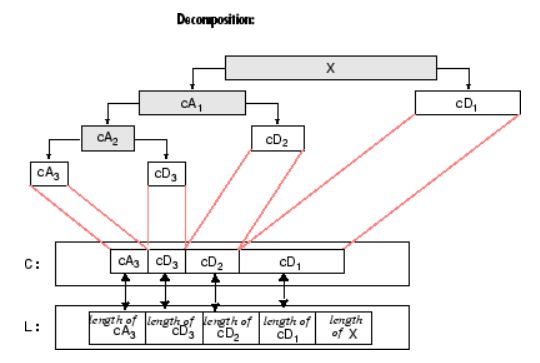

[A1,D1]=lwt(y,LSN);
[A2,D2] = lwt(A1, LSN);
[A3,D3] = lwt(A2, LSN);

In order to invert the decomposition, we need to reverse by feeding backwards. More specifically, the first inversion takes place using the fourth approximation and the fourth detail level. Then, the second inversion takes place by utilizing the first inversion as the approximation and the third detail level. This process is continued until the final inversion which is our full reconstruction.

y1=ilwt(A3,D3,LSN);
y2=ilwt(y1,D2,LSN);
y3=ilwt(y2,D1,LSN);

In order to check that this process works, we can plot the reconstruction and take the infinity norm of the difference between our reconstructed function and our initial function (before applying wavelet transforms). As we can see, the infinity norm yields an error small enough that it can be interpreted as perfect reconstruction. The graph of the reconstructed function looks like our original $y=tanh(x)$ function.

err = norm(y3-y,inf)

err = 1.1102e-16

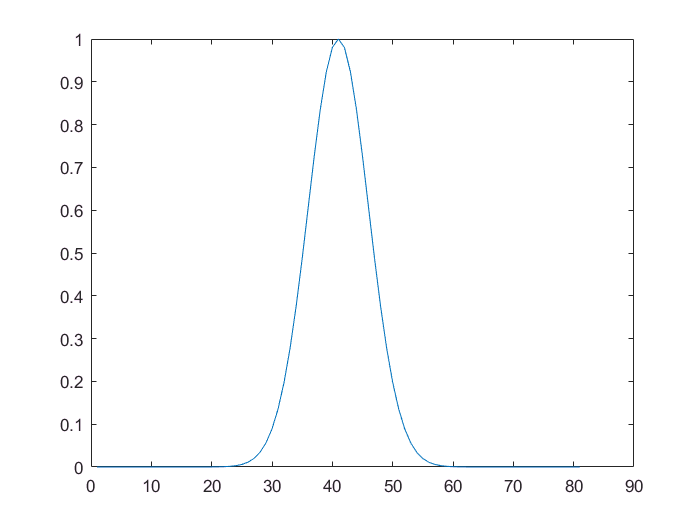

plot(y3)

## With thresholding

In order to begin investigations regarding what happens when removing wavelets deemed 'insignificant', we can threshold the wavelet coefficients that we are generating for this $tanh(x)$function. We begin by setting a threshold $\epsilon$.

e=0.05;

We next apply the wavelet transforms as we did before, except after each application, we remove the wavelet coefficients below the threshold. We do this by searching through the detail vectors to find where the entries are that are below the threshold. We then set these entries to 0.

[A1,D1]=lwt(y,LSN);

I = find(abs(D1)<e);
D1(I) = zeros(size(I));

[A2,D2] = lwt(A1, LSN);

I = find(abs(D2)<e);
D2(I) = zeros(size(I));

[A3,D3] = lwt(A2, LSN);

I = find(abs(D3)<e);
D3(I) = zeros(size(I));

Next, we reverse the transforms in the same way that we did in the previous section (without thresholding). 

y1=ilwt(A3,D3,LSN);
y2=ilwt(y1,D2,LSN);
y3=ilwt(y2,D1,LSN);

We can now investigate the error and see our reconstructed function.

err2=norm(y-y3,inf)

err2 = 0.0259

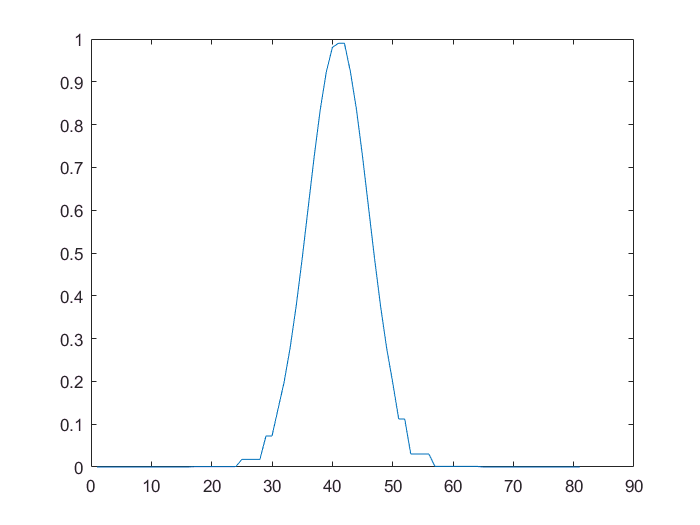

plot(y3)

As can be seen in the plot, some detail is lost in the reconstruction. As is visible, the detail is mostly lost on the areas with shallow gradient rather than the areas with steep gradient. This makes sense, as wavelet coefficients need to be larger to capture a steeper gradient; thus, the smaller magnitude wavelets (which may fall below the threshold) would be in shallower areas. We also see that our infinity norm of error is greater - this is due to the removal of coefficients which give additional detail.

# With n levels

The method above of manually coding each level is not practical if we want to generalize the technique to n levels. Thus, we now create code which utilizes a for loop such that the above technique can be implemented using an arbitrary number of resolution levels.

We begin by defining our initial function more generally. We are demonstrating for n=10, but the below code will work no matter the number of resolution levels chosen. We define our x to be between our bounds but moving up by increments of $\frac{x_{end}-x_{beginning}+\frac{1}{2^j}}{2^j}$ where j>n. The reason that this must be done is because each detail and approximation resolution level has length $\frac{length(x)}{2^i}$ (where i is the resolution level between 1 and n) if the original signal is of even length. . Thus, in order to ensure that the $\frac{length(x)}{2^i}$ value will be an integer for all resolution levels, we must enforce the beginning function in the below way.

clear
n=10; %number of levels of resolution analyzed. 
j=11;
xend=4;
xbeg=-4;
lenneeded =length(xbeg:(xend-xbeg +(1/2^(j)))/(2^(j)):xend); 
x=linspace(xbeg,xend,lenneeded);
x1=linspace(xbeg,xend,lenneeded/2)

x1 =    -4.0000   -3.9922   -3.9844   -3.9765   -3.9687   -3.9609   -3.9531   -3.9453   -3.9374   -3.9296   -3.9218   -3.9140   -3.9062   -3.8983   -3.8905   -3.8827   -3.8749   -3.8671   -3.8592   -3.8514   -3.8436   -3.8358   -3.8280   -3.8201   -3.8123   -3.8045   -3.7967   -3.7889   -3.7810   -3.7732   -3.7654   -3.7576   -3.7498   -3.7419   -3.7341   -3.7263   -3.7185   -3.7107   -3.7028   -3.6950   -3.6872   -3.6794   -3.6716   -3.6637   -3.6559   -3.6481   -3.6403   -3.6325   -3.6246   -3.6168


y1=tanh(x1);
y2=-tanh(x1);
y=[y1 y2];
%y= gaussmf(x,[0.5 0]);

The next step is to initialize matrices in which we will store the approximation vectors and the detail vectors. More specifically, we want to make the approximation matrix have n rows (as each row will be a vector for a different resolution leve) and be of length $\frac{length(x)}{2}$  as the maximum size of an approximation vector will be at resolution level 1. Similarly, we want to make the detail matrix have n rows and be of length $\frac{length(x)}{2}$.

len=length(x); 
App=zeros(n, (length(x))/2);
Dt=zeros(n,[length(x)]/2); 

We then initialize lifting. This is done in the same way as in the previous case with just 3 levels.

LS=liftwave('lazy');
ElimLiftStep = {'d',-1,0}; %Dual lifting step
LSNalmost=addlift(LS,ElimLiftStep,'end');
elsprimal = {'p',1/2,0}; %Primal lifting step
LSN = addlift(LSNalmost,elsprimal,'end'); %Adds lifting

We perform the first decomposition. The output gets stored as the first row of the respective initialized matrices for detail and approximation.

[App(1,:),Dt(1,:)]=lwt(y,LSN);

The next decompositions are performed utilizing a for loop. The lifting wavelet transform is performed on the approximation from the level previous. This is shown in the code as 'Ex'. Ex is found by looking at the previous row in the approximation matrix and then extracting the vector of the appropriate length. Given that for an approximation at level i-1, the vector is of length $\frac{length(x)}{2^{i-1}}$, we we extract that length from the matrix. Then result from the lifting wavelet transform is stored in the approximation matrix at level i, and the detail matrix at level i. Again, the lengths specified correlate to how long an approximation or detail vector is at level i (approximation is length $\frac{length(x)}{2^{i}}$ while detail is $\frac{length(x)}{2^{i}}$).

for i=2:n
    Ex = App(i-1,1:((length(x))/(2^(i-1))));
[App(i,1:((len/(2^i)))),Dt(i,1:(len/(2^i)))] = lwt(Ex, LSN);
end

## Option for thresholding

If we are thresholding, we run the below code which sets a threshold and then sets entries in the detail matrix that are below this threshold to 0. If we are not thresholding, this code should be commented out

e=0.01;
I=find(abs(Dt)<e);
Dt(I)=zeros(size(I));

## Back to general case

The next step is to invert the wavelet transform to check how that the reconstruction was perfect (in the case of no thresholding) or assess the effectiveness of the reconstruction (in the case of thresholding). We first initialize a matrix where we will store our reconstruction at each level. We then begin by doing our first inversion and saving it in the first row of the reconstruction matrix. The inverse wavelet transform is performed using the highest level approximation and the highest level of detail (level n). These vectors should be of length $\frac{length(x)}{2^{n}}$.

yt= zeros(n, (length(x)));
yt(1, 1:((len/(2^(n-1)))))=ilwt(App(n,1:((len/(2^n)))),Dt(n,1:(len/(2^n))),LSN);

We now write a for loop which will complete all the remaining inversions and then store them in the reconstruction matrix. It is important to note here that the reconstruction numbering is reversed from the approximation/detail numbering. Thus, for example, y2 in a 10 level reconstruction reconstructed using the previous reconstruction level (y1) as the approximation and the detail level associated with y9 (the second entry if reversed numbering). Similarly, y3 would be reconstructed using y2 as the approximation and y8 (the third entry if reversed numbering).

for i=2:n
    yt(i, 1:(len/(2^(n-i))))=ilwt(yt(i-1, 1:(len/(2^((n-i+1))))),Dt((n+1-i),1:(len/(2^(n-i+1)))),LSN); %reconstruct up all levels
end

The final row in the reconstruction matrix is our full reconstruction. Thus, we apply the infinity norm of error onto yt(n,:) and we plot that row against x.

err = max(abs(yt(n,:)-y))

err = 0.0082

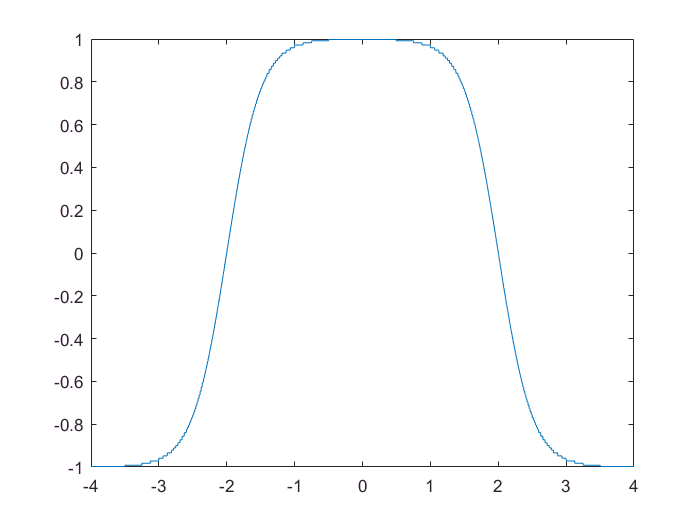

plot(x,yt(n,:))

# Error Analysis

In order to get some more information regarding the way that thresholding affects error, we performed some deeper error analysis. The first error plot was designed to perform the above code but with many different thresholds. A graph is then created which denotes the infinity error versus the threshold. The code inside the for loop is largely the same as the above section. The differences are marked as comments on the below code snippet. The second error plot is designed to plot the percent of dropped points versus the error of the infinity norm. The percent of dropped points is calculated by finding the number of points that are below the threshold and above 0. We want the above 0 condition enforced because the matrix fills in the remaining part of the shorter vectors with zeroes. Then, we find the total number of points as the sum of all the vector lengths. This gives us the necessary information for percentage of points dropped

for j=1:2000 %choosing how many different epsilons to test
e=1.5E-5*j; %setting an epsilon
ep(j,:)=e; %vary threshold and keep track

len=length(x); 
App=zeros(n, (length(x))/2); 
Dt=zeros(n,[length(x)]/2); 

LS=liftwave('lazy');
ElimLiftStep = {'d',-1,0}; 
LSNalmost=addlift(LS,ElimLiftStep,'end');
elsprimal = {'p',1/2,0}; 
LSN = addlift(LSNalmost,elsprimal,'end');

[App(1,:),Dt(1,:)]=lwt(y,LSN);

for i=2:n
    Ex = App(i-1,1:((length(x))/(2^(i-1))));
[App(i,1:((len/(2^i)))),Dt(i,1:(len/(2^i)))] = lwt(Ex, LSN);
end

I0=find(0<abs(Dt) & abs(Dt)<e); %details that aren't just 0s filling in the rows of the matrices and are less than epsilon
for i=1:n
    S(i)=len/(2^i); %size of Dt things 
end

I=find(abs(Dt)<e);
Dt(I)=zeros(size(I));
perdrop(j,:)= [prod(size(I0))/sum(S)]*100; %yields percentage of points dropped

yt= zeros(n, (length(x)));
yt(1, 1:((len/(2^(n-1)))))=ilwt(App(n,1:((len/(2^n)))),Dt(n,1:(len/(2^n))),LSN); %start with y1, reconstruct

for i=2:n
    yt(i, 1:(len/(2^(n-i))))=ilwt(yt(i-1, 1:(len/(2^((n-i+1))))),Dt((n+1-i),1:(len/(2^(n-i+1)))),LSN); %reconstruct up all levels
end

err(j,:) = max(abs(yt(n,:)-y)); %check perfect reconstruction
end

Now, that we have all the necessary data with the above for loop we can create plots demonstrating our results. 

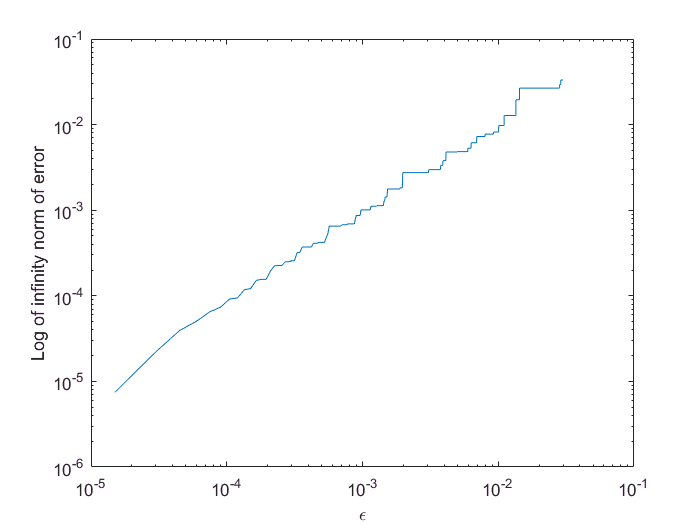

loglog(ep,err)
ylabel('Log of infinity norm of error')
xlabel('\epsilon')

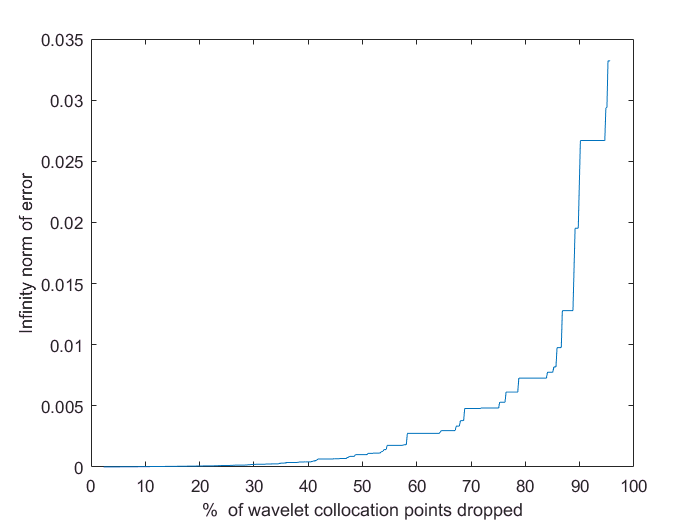


plot(perdrop,err)
ylabel('Infinity norm of error')
xlabel('%  of wavelet collocation points dropped')

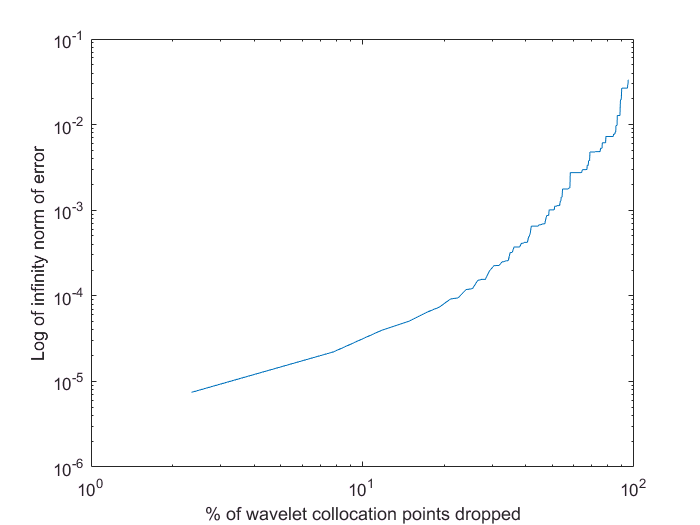

loglog(perdrop,err)
ylabel('Log of infinity norm of error')
xlabel('% of wavelet collocation points dropped')

Another type of error analysis that we can do is see where wavelets are maintained given a certain threshold.

To see a plot like this, look at locationsofwavelets.m

We can also do a contour plot as shown below.

nbcol=100;

nbcol = 100

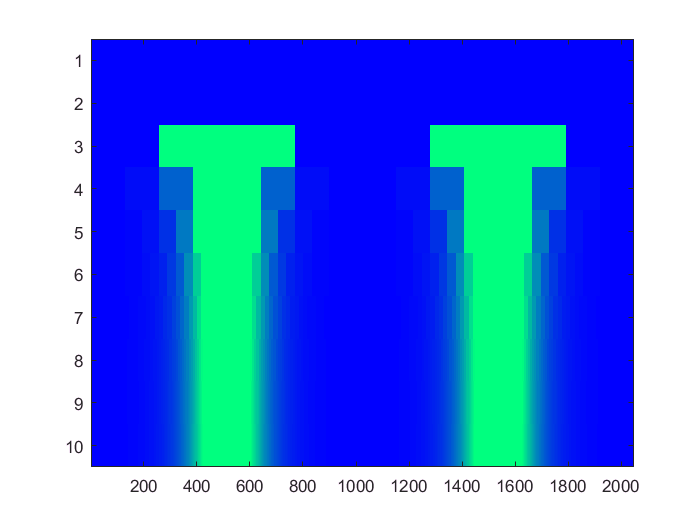

[App(1,:),Dt(1,:)]=lwt(y,LSN); %first decomposition


%Below is the code for subsequent decompositions. Note that the size of
%each successive level is the previous level/2
for i=2:n
    Ex = App(i-1,1:((length(x))/(2^(i-1))));
[App(i,1:((len/(2^i)))),Dt(i,1:(len/(2^i)))] = lwt(Ex, LSN);
end

%%contour map
for i=1:n
d=Dt(i,1:len/(2^(i)));
d = d(:)';
d = d(ones(1,len/2^(n-i+1)),:);
cfd(i,:) = wkeep1(d(:)',len);
end

cfd=abs(cfd);
cfd=wcodemat(cfd,nbcol,'row');
colormap(winter)
image(cfd)
tics = 1:n;

labs = int2str((fliplr(tics))');
ax = gca;
ax.YTickLabelMode = 'manual';
ax.YDir = 'normal';
ax.Box = 'On';
ax.YTick = tics;
ax.YTickLabel = labs;

## Reconstruct with only certain levels

We can plot what happens if we do a reconstruction with only a certain number of levels. 

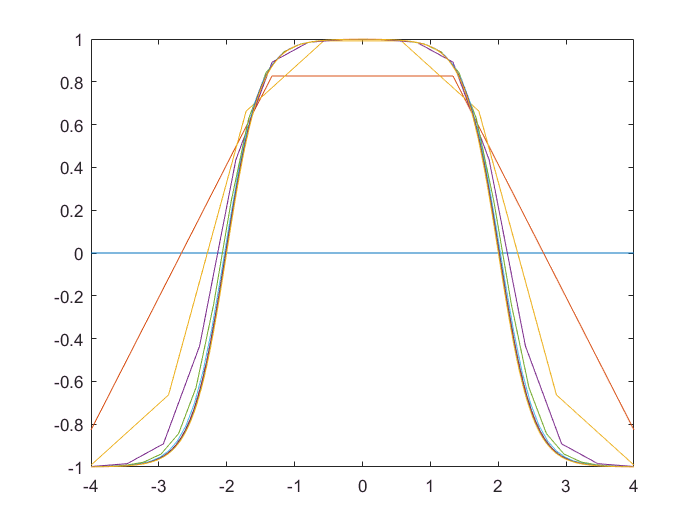

clear
j=10;
n=10;%number of levels of resolution analyzed. 
xend=4;
xbeg=-4;
lenneeded =length(xbeg:(xend-xbeg +(1/2^(j)))/(2^(j)):xend); 
x=linspace(xbeg,xend,lenneeded);
nbcol=100;
%y= gaussmf(x,[0.1 0])';
x1=linspace(xbeg,xend,lenneeded/2);
y1=tanh(x1);
y2=-tanh(x1);
y=[y1 y2];



len=length(x); 
App=zeros(n, (length(x))/2); 
Dt=zeros(n,[length(x)]/2); 

LS=liftwave('lazy');
ElimLiftStep = {'d',-1,0};  
LSNalmost=addlift(LS,ElimLiftStep,'end');
elsprimal = {'p',1/2,0}; %Primal lifting step
LSN = addlift(LSNalmost,elsprimal,'end'); %adds lifting

[App(1,:),Dt(1,:)]=lwt(y,LSN); %first decomposition

for i=2:n
    Ex = App(i-1,1:((length(x))/(2^(i-1))));
[App(i,1:((len/(2^i)))),Dt(i,1:(len/(2^i)))] = lwt(Ex, LSN);
end

yt= zeros(n, (length(x)));
yt(1, 1:((len/(2^(n-1)))))=ilwt(App(n,1:((len/(2^n)))),Dt(n,1:(len/(2^n))),LSN); %start with y1, reconstruct

for i=2:n
    yt(i, 1:(len/(2^(n-i))))=ilwt(yt(i-1, 1:(len/(2^((n-i+1))))),Dt((n+1-i),1:(len/(2^(n-i+1)))),LSN); %reconstruct up all levels
end

for z=1:n
%z=2; %choose how many levels of reconstruction to plot
plot(linspace(-4,4,len/2^(n-z)),yt(z, 1:(len/(2^(n-z)))));
hold on;
end
hold off;

%ensure that it preserves the mean
for z=1:n
w(z)=mean(y)-mean(yt(z, 1:(len/(2^(n-z)))));
end

if w<eps %machine epsilon
    disp('True')
else
    disp('False')
end

True
